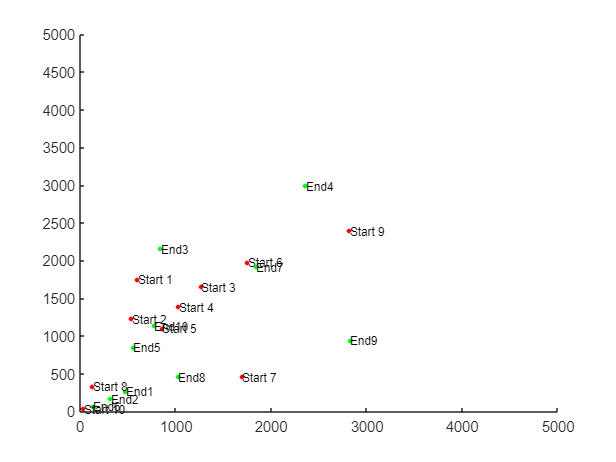

clc;
clear;
rng(216)
%Import Parameters
[WaypoinSize,dt,KaE,Kv,xrange,yrange,ArrivalDist,spacing,Kd,Ke,fontsz,perception,KA,KC,KS,GeneratePlot,n] = setParam();

%Initiate drones
Drones = droneInitiate(n);

showDrones('DronesStart',Drones,WaypoinSize,xrange,yrange,fontsz);

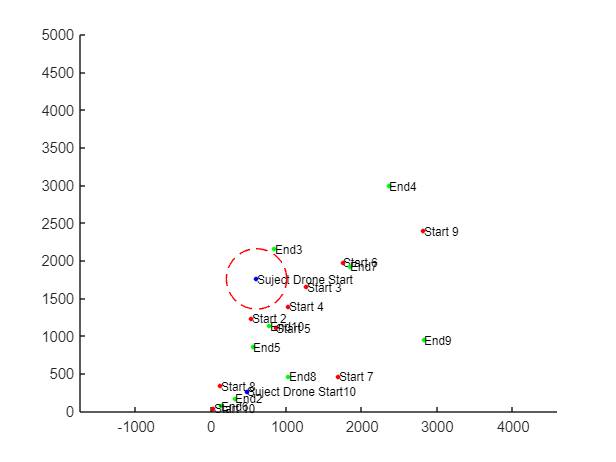

showDronesCircle('circle',Drones,1,WaypoinSize,xrange,yrange,fontsz,perception);
axis equal

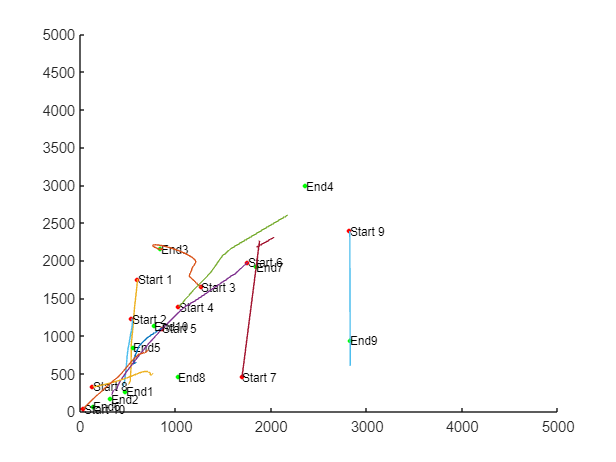

[ContourPlot , Reward] = RewardContour(Drones,xrange,yrange,spacing,Kd,Ke,WaypoinSize,GeneratePlot,fontsz);

Iterations = 0;
terminate = false;

while terminate == false && Iterations < 5000
Iterations = Iterations + 1;
Drones = flock(Drones,perception,KA,KC,KS);

Drones = Forces(Drones,KaE,Kv);

[Drones, terminate] = UpdateV2(Drones,dt,ArrivalDist);

end

showDrones('DronesStart',Drones,WaypoinSize,xrange,yrange,fontsz);